# Problem 21.32

clear
constant

k = 8.9900e+09

e0 = 8.8500e-12

e = 1.6020e-19

syms q2 x1 x real
assume(x>0), assume(x1>0)
q3 = 8*e

q3 = 1.2816e-18

$q_1$ must be positive, thus $q_1 = 8e$

q1 = 8*e

q1 = 1.2816e-18

q = [q1 q3]

q = 1.0e-17 *

    0.1282    0.1282


u = [1; -1]  % direction sign of displacement of 2 wrt 1 and 3, respectively

u =      1
    -1


r = [x1 x]

$$r = \left(\begin{array}{cc} x_{1} & x \end{array}\right)$$

F2net = vpa( k*q*q2./r.^2*u , 3)

$$F2net = \frac{1.15e-8\,q_{2}}{{x_{1}}^{2}}-\frac{1.15e-8\,q_{2}}{x^{2}}$$

Find $x_1$

x1s = solve(subs(F2net,x,0.4)==0,x1)    % answer

$$x1s = 0.4$$

F2net = subs(F2net,x1,x1s)

$$F2net = 0.000000072009900000085790700010690557065\,q_{2}-\frac{0.00000001152158400001372651200171048913\,q_{2}}{x^{2}}$$

then $q_2$

q2s = vpa(solve(subs(F2net,x,inf)==1.5e-25,q2),3)   % answer

$$q2s = 2.08e-18$$

Verification by plotting F2,net using obtained parameters

F2net = vpa(subs(F2net,[x1,q2],[x1s,q2s]),3)

$$F2net = 1.5e-25-\frac{2.4e-26}{x^{2}}$$

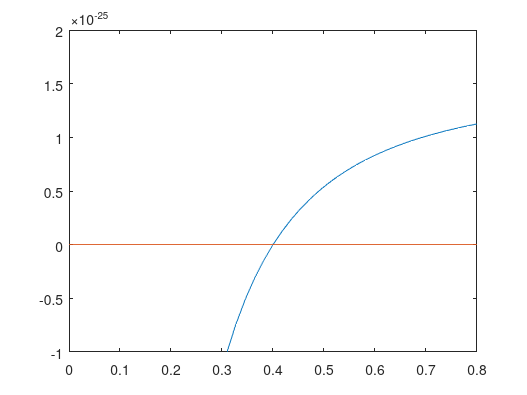

fplot([F2net 0]), xlim([0 0.8]), ylim([-1 2]*1e-25)